## XERCISE

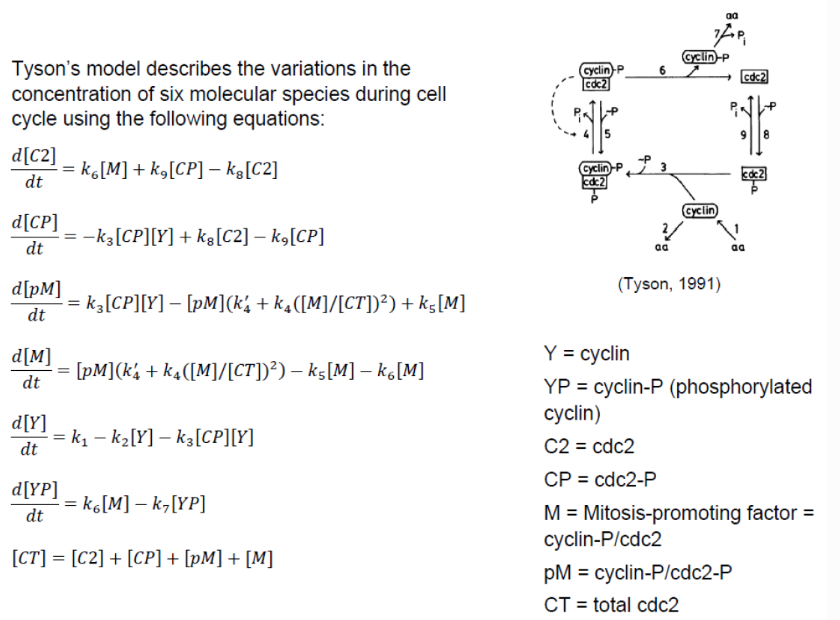

## TASK 1

Plot the evolution of the concentration of Y, YP, C2, CP, M, and pM over 40 minutes using Euler’s method to solve the ODEs.

#### **Theory needed:**

Euler's method is an explicit approach used for obtaining a **numerical approximation** to the solutions of time-dependent [ordinary](https://en.wikipedia.org/wiki/Ordinary_differential_equation) (and [partial) differential equations](https://en.wikipedia.org/wiki/Partial_differential_equation), by calculating the state of a system at a later time from the state of the system at the current :

Solves the problem of **calculating the shape of an unknown curve which starts at a given point and satisfies a given differential equation**.

The idea is that while the curve is initially unknown, its starting point, which we denote by A0, is known (see Figure 1). Then, from the differential equation, the slope to the curve at A0 can be computed, and so, the tangent line.

**Take a small step along that tangent line **up to a point A1. Along this small step, the slope does not change too much, so A1 will be close to the curve. If we pretend that A1 is still on the curve, the same reasoning as for the point A0 above can be used. After several steps, a [polygonal curve](https://en.wikipedia.org/wiki/Polygonal_curve) (A0A1A2A3…) is computed. In general, this curve does not diverge too far from the original unknown curve, and the **error between the two curves can be made small if the step size is small enough and the interval of computation is finite**

**Define all the constants**

k1 = 0.015; % k1/[CT]
k2 = 0;
k3 = 200; % k3*[CT]
k4 = 180; k4prime = 0.018;
k5 = 0; k6 = 1; k7 = 0.6; k9 = 10*k6; k8 = 10*k9;

dt = 2e-4;                              % setting a small step here as needed by Euler's method
tlast = 40;                             % defining the finite time interval in which we want to apply the method as required
iterations = round(tlast/dt);

time = zeros(iterations,1);
Yall = zeros(iterations,1);
YPall = zeros(iterations,1);
C2all = zeros(iterations,1);
Mall = zeros(iterations,1);
pMall = zeros(iterations,1);
Y=0.1; YP = 0.1; C2 = 0.5; CP = 0.5; M = 0.1; pM = 0.1;         % defining the starting point as needed by the method

k1 = k1*(C2+CP+M+pM);                   % DOUBT: why am I doing this?
k3 = k3/(C2+CP+M+pM);

**applying Euler's method:**

for i=1:iterations
    time(i) = (i-1)*dt;
    Yall(i) = Y;                        % storing the coordinates of y-axis coordinates of the point
    YPall(i) = YP;
    C2all(i) = C2;
    CPall(i) = CP;
    Mall(i) = M;
    pMall(i) = pM;
    CT = C2 + CP + pM + M;

    dY = k1 - k2*Y - k3*CP*Y;           % finding the y-axis difference upon our time step
    dYP = -k7*YP + k6*M;
    dC2 = k6*M + k9*CP - k8*C2;
    dCP = -k3*CP*Y + k8*C2 - k9*CP;
    dM = -k6*M -k5*M + pM*(k4prime + k4*(M/CT)^2);
    dpM = k3*CP*Y - pM*(k4prime + k4*(M/CT)^2) + k5*M;

    Y = Y + dY*dt;                      % computing the new y-axis coordinate for the next point so that it can be stored in the next loop iteration
    YP = YP + dYP*dt;
    C2 = C2 + dC2*dt;
    CP = CP + dCP*dt;
    M = M + dM*dt;
    pM = pM + dpM*dt;
end

**plotting results:**

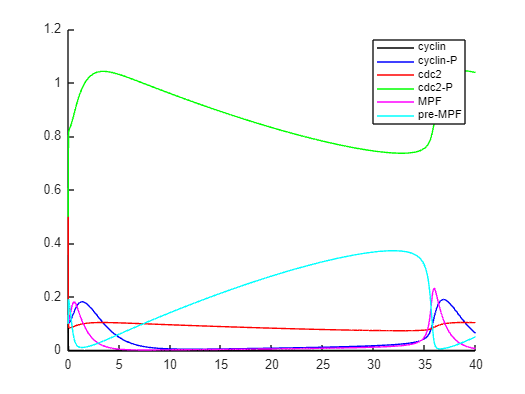

figure
hold on
plot(time, Yall,'k')
plot(time, YPall,'b')
plot(time, C2all,'r')
plot(time, CPall,'g')
plot(time, Mall,'m')
plot(time, pMall,'c')
legend('cyclin','cyclin-P','cdc2','cdc2-P','MPF','pre-MPF')

In the plot we can see that all the curves have a cyclic behavoiur. This is very evident for the MPF

## task 2

Plot the evolution of the concentration of Y, YP, C2, CP, M, and pM over 200 minutes using Matlab ODE solver. Reproduce figure 3A of the original paper from Tyson (1991).

**Setting up everything:**

We first have to define the function containig the differential equation of the system which will be solved with ode45

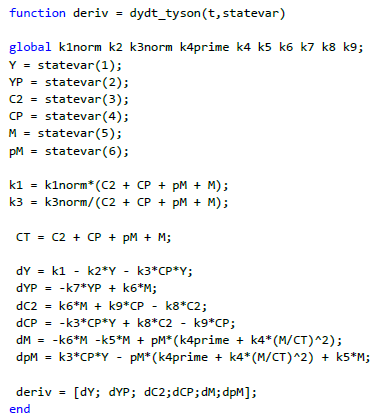

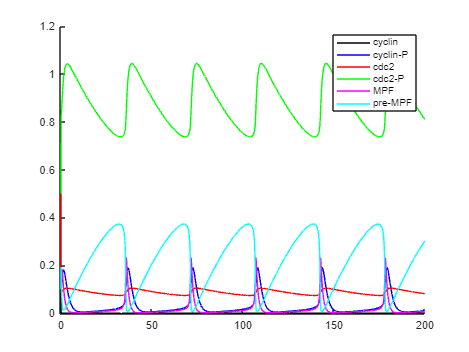

global k1norm k2 k3norm k4prime k4 k5 k6 k7 k8 k9;              %DOUBT: why do I need to set these variables as global both here in the script and in the function?

k1norm = 0.015;
k2 = 0;
k3norm = 200;
k4 = 180; k4prime = 0.018;
k5 = 0; k6 = 1; k7 = 0.6; k9 = 10*k6; k8 = 10*k9;

tlast = 200;

Y = 0.1;
YP = 0.1;
C2 = 0.5;
CP = 0.5;
M = 0.1;
pM = 0.1;

statevar_i = [Y,YP,C2,CP,M,pM];
[time,statevars] = ode45(@dydt_tyson, ...
                         [0,tlast], ...
                         statevar_i);            %DOUBT: why the @?  what is the 45?

Y = statevars(:,1);
YP = statevars(:,2);
C2 = statevars(:,3);
CP = statevars(:,4);
M = statevars(:,5);
pM = statevars(:,6);

figure
hold on
plot(time, Y,'k')
plot(time, YP,'b')
plot(time, C2,'r')
plot(time, CP,'g')
plot(time, M,'m')
plot(time, pM,'c')
legend('cyclin','cyclin-P','cdc2','cdc2-P','MPF','pre-MPF')

As we can see we are plotting over a much longer time interval, so the cyclic behaviour of the molecular species is more clear. All six molecular species display the cyclic behaviour.

Reproducing figure 3A of the paper:

"The curves are total cyclin ([YT] = [Y] + [YP] + [pM] + [M]) and active MPF [Ml] relative to total cdc2 ([CT] = [C2] + [CP] + [pM] + [MI)."

"(a) Limit cycle oscillations for k4 = 180 min-', k6 = 1 min- (point x in Fig. 2). A "limit cycle" solution of a set of ordinary differential equations is a periodic solution that is asymptotically stable with respect to small perturbations in any of the dynamical variables"

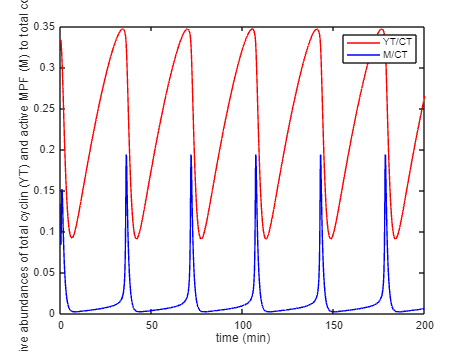

CT = C2 + CP + pM + M;
YT = Y + YP + pM + M;

figure
plot(time,YT./CT,'r','DisplayName','YT/CT')                       %DOUBT: why are these two plot useful???
hold on
plot(time,M./CT,'b','DisplayName','M/CT')
legend('Location','ne')
xlabel('time (min)') 
ylabel('relative abundances of total cyclin (YT) and active MPF (M) to total cdc [CT]') 

## task 3

On a single graph, plot the concentration of MPF over time for the following values of 𝑘6: 0.2 min-1, 1 min-1, and 5 min-1. How does its oscillatory behaviour change?

(So we want to see how the value of k6 influences the cell cycle)

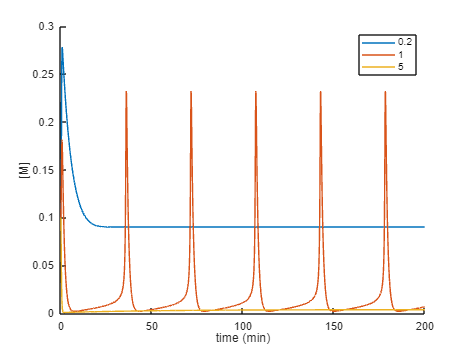

global k1norm k2 k3norm k4prime k4 k5 k6 k7 k8 k9;
k1norm = 0.015;
k2 = 0;
k3norm = 200;
k4 = 180;
k4prime = 0.018;
k5 = 0;k7 = 0.6;

tlast = 200;
Y = 0.1;
YP = 0.1;
C2 = 0.5;
CP = 0.5;
M = 0.1;
pM = 0.1;

statevar_i = [Y,YP,C2,CP,M,pM];
figure
hold on
for k6=[0.2 1 5]
    k9 = 10*k6;
    k8 = 10*k9;
    [time,statevars] = ode45(@dydt_tyson, ...
                             [0,tlast], ...
                             statevar_i);
    M = statevars(:,5);
    plot(time,M,'DisplayName',num2str(k6))
    xlabel('time (min)') 
    ylabel('[M]') 
end
legend()

Concentration of MPF for different concentration of k6.

    • k6 = 1               cyclic behaviour

    • k6=0.2              we have a stable concentration at high level.

    • k6=5                 we don't have MPF (stable concentration 0).

**k6 regulates the degradation of MPF** 

    so decreasing it may lead to a stable concentration of MPF 

    or if the degradation is too fast we may not have MPF.

In agreement with what shown in figure 2 of the paper: